# Labolatorium 3 - Modulacja amplitudy, Demodulacja dla AM, DSB AM i SSB AM 

Definiujemy nośną jako $c=A_c \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_c t\right)$ oraz sygnały modulujące jako  $m_1 =A_m \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_m t\right)$  m2 - sygnał prostokątny (przeskok fazy, K<-1) $m_3 =A_m \textrm{∙}\sum_{i=1}^{10} \mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi it\right)$

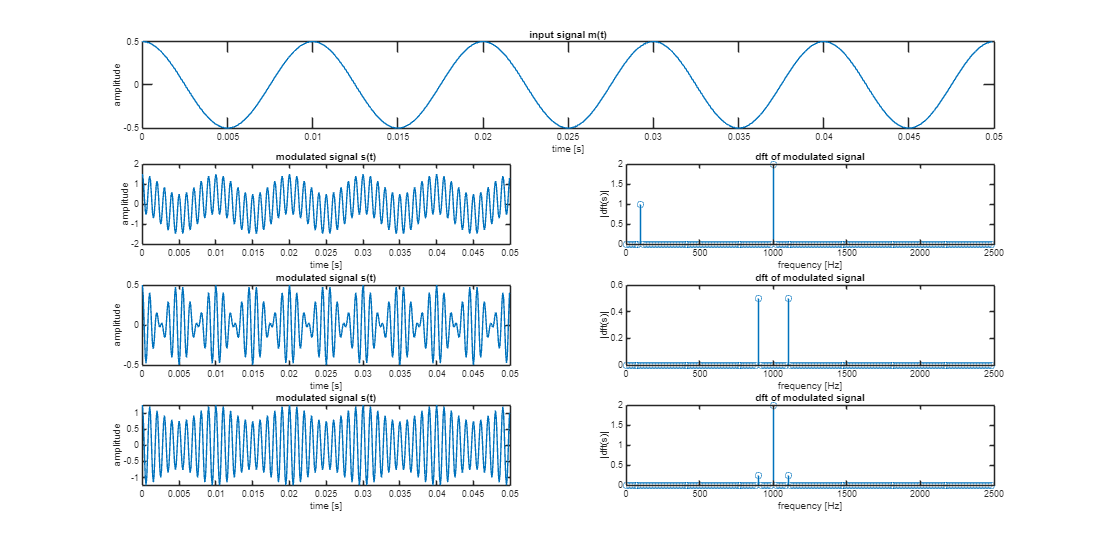

%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.5;
fm = 100;
K = -0.5;

k = Am / Ac;

%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);

%---------------------definicja m1-----------------------------


m1 = Am *cos(2*pi*fm*t);

s1_m1 = c + m1;
s1_m1_fft = fft(s1_m1);

s2_m1 = c .* m1;
s2_m1_fft = fft(s2_m1);

s3_m1 = c .* (1 + m1*k);
s3_m1_fft = fft(s3_m1);

%---------------------definicja m2-----------------------------


m2 = [ones(1, length(t)/2), K * ones(1, length(t)/2)];

s1_m2 = c + m2;
s1_m2_fft = fft(s1_m2);

s2_m2 = c .* m2;
s2_m2_fft = fft(s2_m2);

s3_m2 = c .* (1 + m2*k);
s3_m2_fft = fft(s3_m2);

%---------------------definicja m3-----------------------------
m3 = 0;
for i = 1:10
    m3 = m3 + Am * cos(2*pi*fm*i*t);
end

s1_m3 = c + m3;
s1_m3_fft = fft(s1_m3);

s2_m3 = c .* m3;
s2_m3_fft = fft(s2_m3);

s3_m3 = c .* (1 + m3*k);
s3_m3_fft = fft(s3_m3);


fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 2, [1,2])
plot(t, m1)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 2, 3)
plot(t, s1_m1)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,4)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 5)
plot(t, s2_m1)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,6)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 7)
plot(t, s3_m1)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')

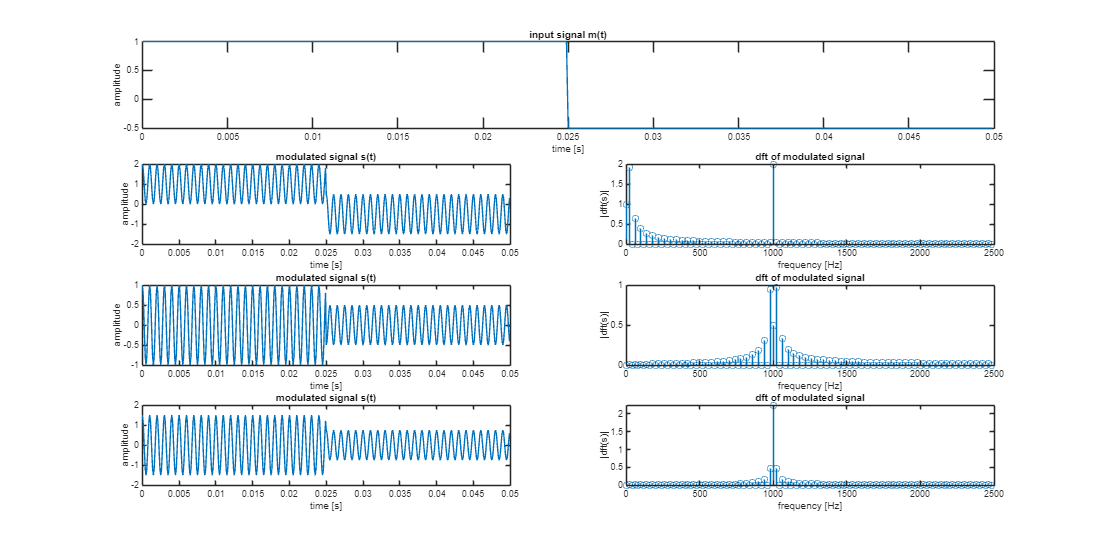

fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 2, [1,2])
plot(t, m2)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 2, 3)
plot(t, s1_m2)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,4)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m2_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 5)
plot(t, s2_m2)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,6)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m2_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 7)
plot(t, s3_m2)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m2_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')

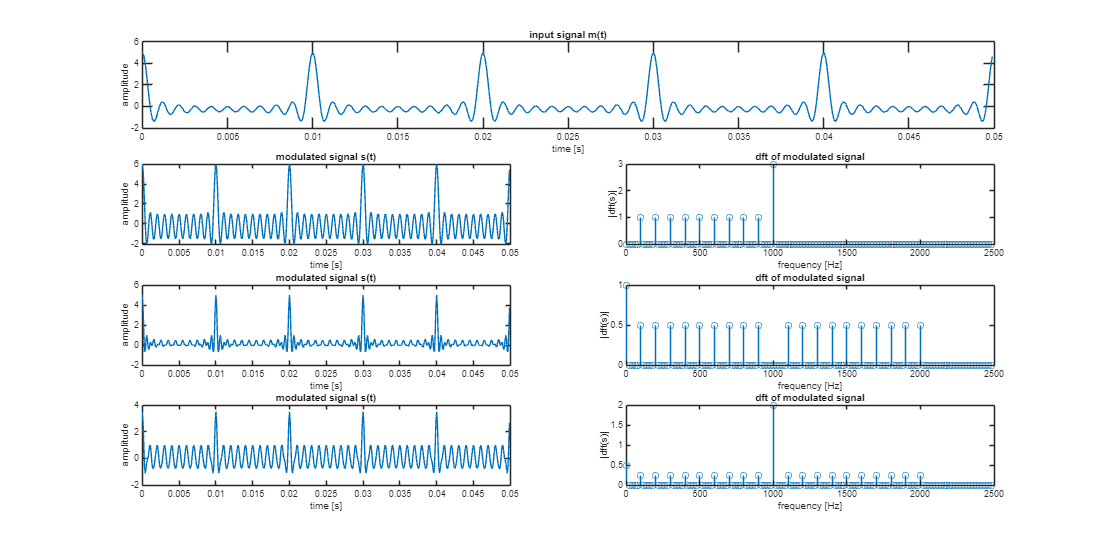




fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 2, [1,2])
plot(t, m3)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 2, 3)
plot(t, s1_m3)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,4)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m3_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 5)
plot(t, s2_m3)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,6)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m3_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4, 2, 7)
plot(t, s3_m3)
title('modulated signal s(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4,2,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m3_fft(1:length(t)/4)/length(k)))
title('dft of modulated signal')
xlabel('frequency [Hz]')
ylabel('|dft(s)|')